# Tde 03Feb2022

## Q3

clear;
clc;

syms q1 q2 q3
qv = [q1 q2 q3];

% 3R robot inverse kinematics for qdotdot
p = [cos(q1)+cos(q1+q2)+cos(q1+q2+q3);
    sin(q1)+sin(q1+q2)+sin(q1+q2+q3)];
Jq = jacobian(p,qv)

$$Jq = \left(\begin{array}{ccc} -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

J2 = SecondOrdJacobian(Jq, qv)

$$J2 = \left(\begin{array}{ccc} \sin\left(q_{1}+q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right)\\ -\cos\left(q_{1}+q_{2}+q_{3}\right) & -\cos\left(q_{1}+q_{2}+q_{3}\right) & -\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

## Q4

clear;
clc;

% % Define the points (replace with actual values)
% T = 100;
% ta = [0, T/2]; % Time points
% tb = [T/2, T]; % Time points
% q_start1 = 0; % Start position
% q_mid1 = 0.5318; % Mid position
% q_end1 = 3; % End position
% q_start2 = pi/2;
% q_mid2 = 0.2527;
% q_end2 = pi/2;
% 
% % Create the spline
% spline_traja1 = spline(ta, [q_start, q_mid]);
% spline_traja2 = spline(ta, [q_start, q_mid]);
% spline_trajb1 = spline(tb, [q_start, q_mid]);
% spline_trajb2 = spline(tb, [q_mid, q_end]);
% 
% % Evaluate the spline at a range of points
% t_eval1 = linspace(0, T/2, 100);
% t_eval2 = linspace(T/2, T, 100);
% 
% q_evala1 = ppval(spline_traja1, t_eval1);
% q_evala2 = ppval(spline_traja2, t_eval2);
% 
% q_evalb1 = ppval(spline_trajb1, t_eval1);
% q_evalb2 = ppval(spline_trajb2, t_eval2);
% 
% % Plot the trajectory
% figure
% plot(t_eval1, q_evala1);
% xlabel('Time');
% ylabel('Joint Position');
% title('q1a');
% hold on
% plot(t_eval2, q_evalb1, 'r');
% xlabel('Time');
% ylabel('Joint Position');
% title('q1b');
% 
% figure
% plot(t_eval1, q_evala2);
% xlabel('Time');
% ylabel('Joint Position');
% title('q2a');
% hold on
% plot(t_eval2, q_evalb2, 'r');
% xlabel('Time');
% ylabel('Joint Position');
% title('q2b');

% [cofs, vels] = splines(tvals, qvals);
% 
% coeffs = splines_norm_compute_coeffs(tvals, qvals, v1, vn, print_info)
% spline_plot_norm(tvals, coeffs)

syms q1 q2 L
qv = [q1 q2];
f = [q1+cos(q2)*L; sin(q2)];
J = jacobian(f, qv)

$$J = \left(\begin{array}{cc} 1 & -L\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{2}\right) \end{array}\right)$$

dJ = det(J)

$$dJ = \cos\left(q_{2}\right)$$

$$J = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

ans =      2


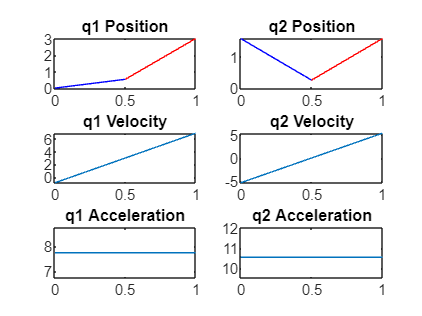

% Given data has been included directly within the script
% Define time intervals
T = 1; % Total period
t1 = linspace(0, T/2, 100); % First half
t2 = linspace(T/2, T, 100); % Second half

% Define the values at the knots for the splines
values_q1_first = [0 0.5318]; % q1 values for the first half
values_q2_first = [pi/2 0.2527]; % q2 values for the first half
values_q1_second = [0.5318 3]; % q1 values for the second half
values_q2_second = [0.2527 pi/2]; % q2 values for the second half

% Spline interpolation for the first half
spline_q1_first = spline([0 T/2], values_q1_first);
spline_q2_first = spline([0 T/2], values_q2_first);

% Spline interpolation for the second half
spline_q1_second = spline([T/2 T], values_q1_second);
spline_q2_second = spline([T/2 T], values_q2_second);

% Plotting
figure;
subplot(3,2,1);
plot(t1, ppval(spline_q1_first, t1), 'b', t2, ppval(spline_q1_second, t2), 'r');
title('q1 Position');

subplot(3,2,2);
plot(t1, ppval(spline_q2_first, t1), 'b', t2, ppval(spline_q2_second, t2), 'r');
title('q2 Position');

subplot(3,2,3);
plot(t, q1_vel);
title('q1 Velocity');

subplot(3,2,4);
plot(t, q2_vel);
title('q2 Velocity');

subplot(3,2,5);
plot(t, q1_acc);
title('q1 Acceleration');

subplot(3,2,6);
plot(t, q2_acc);
title('q2 Acceleration');

% Compute and plot velocities and accelerations as required
% For demonstration, only position plots are fully defined
% Follow a similar procedure for velocity and acceleration plots,
% deriving from the spline functions and plotting them in blue and red
